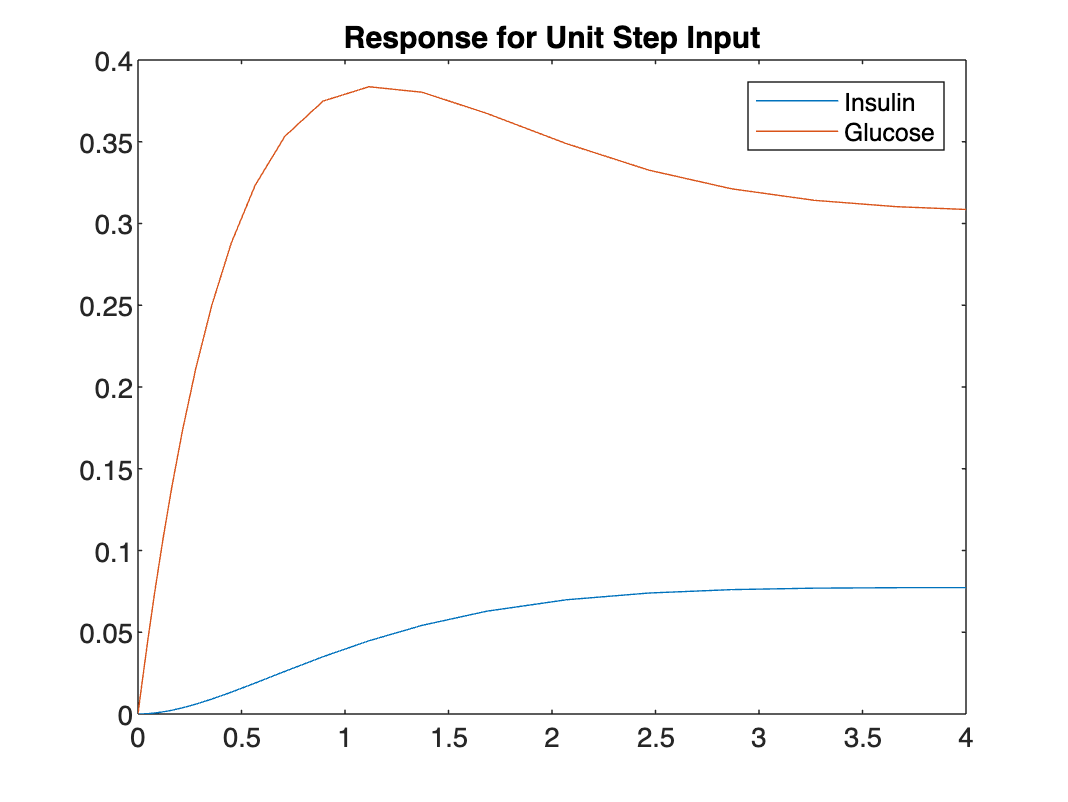

%Unit Step Input
[t,y]=ode23('plasmaGlucoseUnitStep',[0 4],[0 0]); 
plot(t,y) 
title('Response for Unit Step Input'); 
legend('Insulin','Glucose'); 

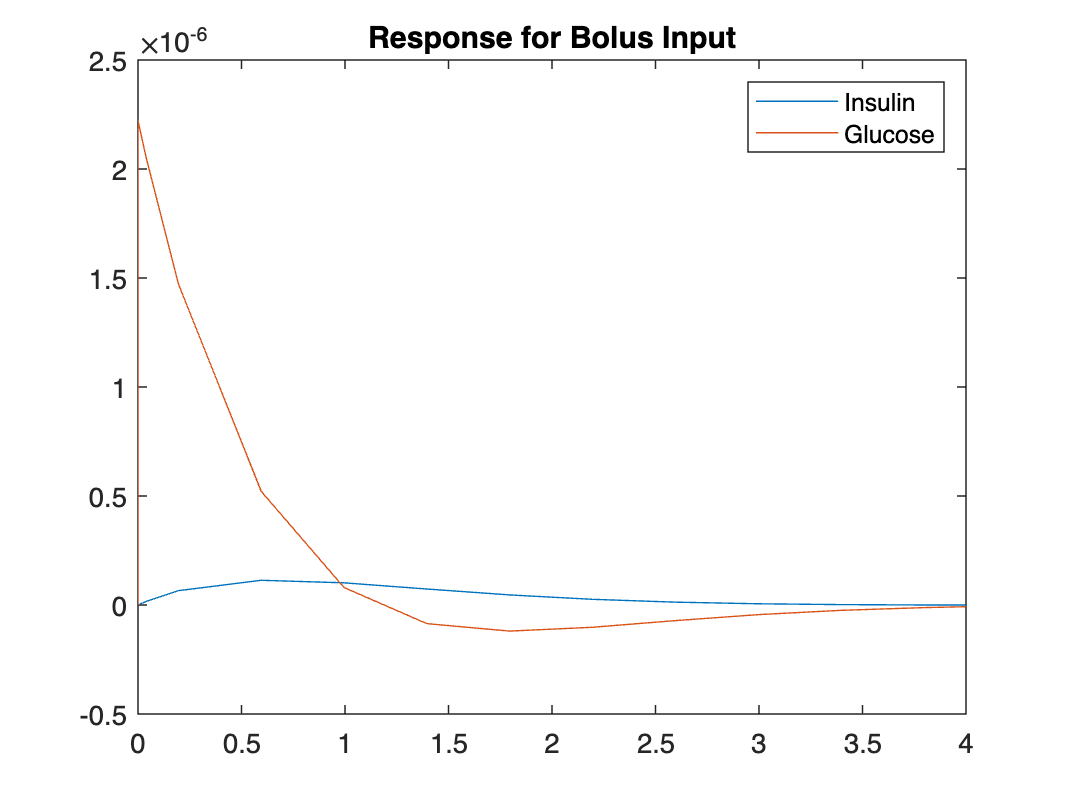

%Bolus Input
[t,y]=ode23('plasmaGlucoseBolus',[0 4],[0 0]); 
plot(t,y) 
title('Response for Bolus Input'); 
legend('Insulin','Glucose'); 

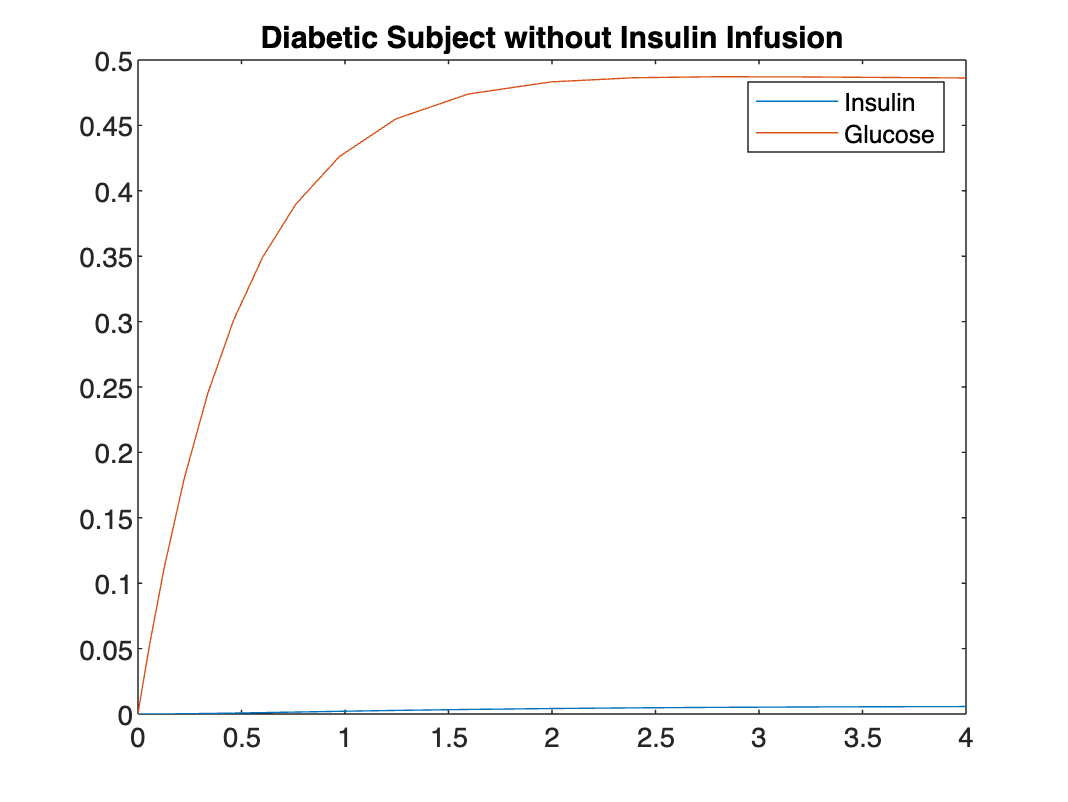

%Diabetic subject without insulin infusion
[t,y]=ode23('diabeticWithoutInsulin',[0 4],[0 0]); 
plot(t,y) 
title('Diabetic Subject without Insulin Infusion'); 
legend('Insulin','Glucose'); 

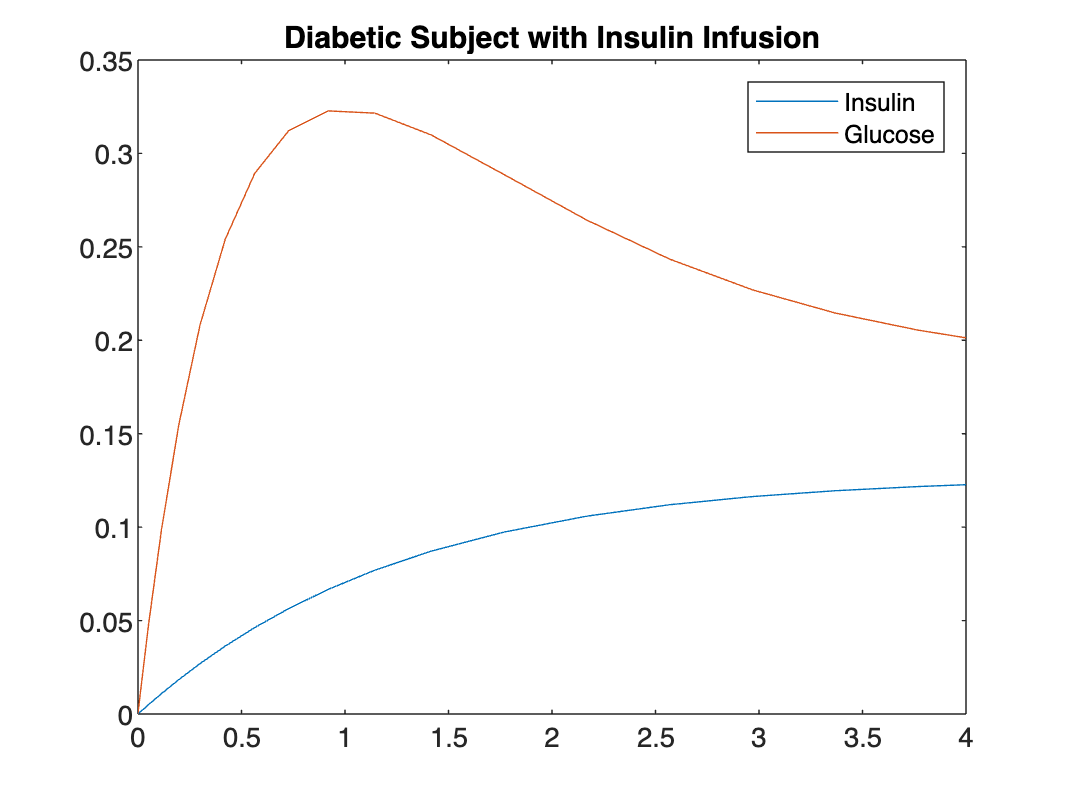

%Diabetic subject with insulin infusion of 100 mU/kg/h
[t,y]=ode23('diabeticWithInsulin',[0 4],[0 0]); 
plot(t,y) 
title('Diabetic Subject with Insulin Infusion'); 
legend('Insulin','Glucose'); 

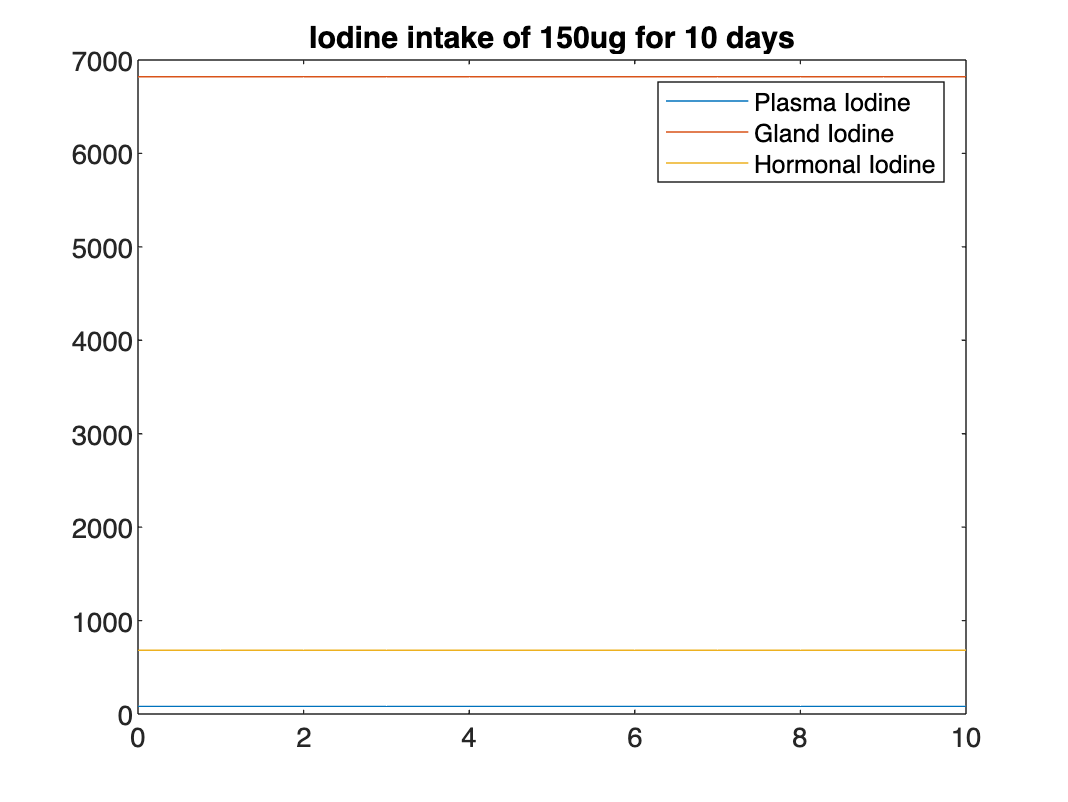

%Iodine intake of 150ug for 10 days
[t,y] = ode23('riggs150',[0 10],[81.2 6821 682]); 
plot(t,y)
title('Iodine intake of 150ug for 10 days'); 
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

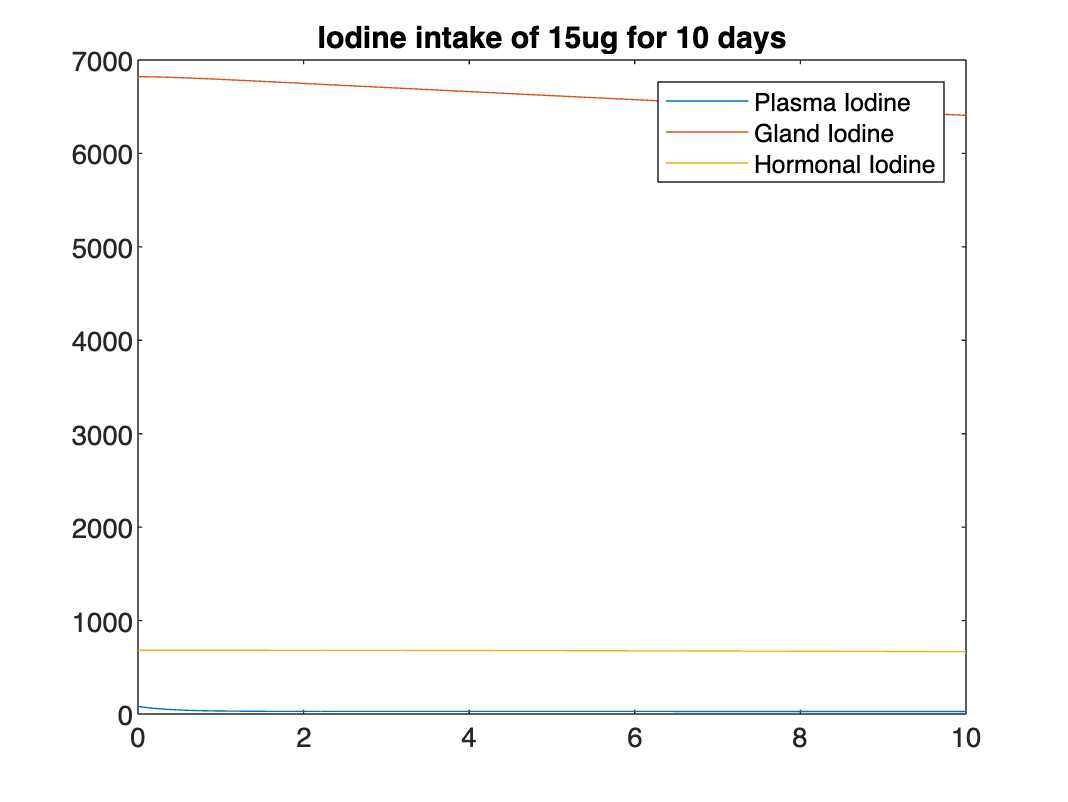

%Iodine intake of 15ug for 10 days
[t,y] = ode23('riggs15',[0 10],[81.2 6821 682]); 
plot(t,y)
title('Iodine intake of 15ug for 10 days'); 
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

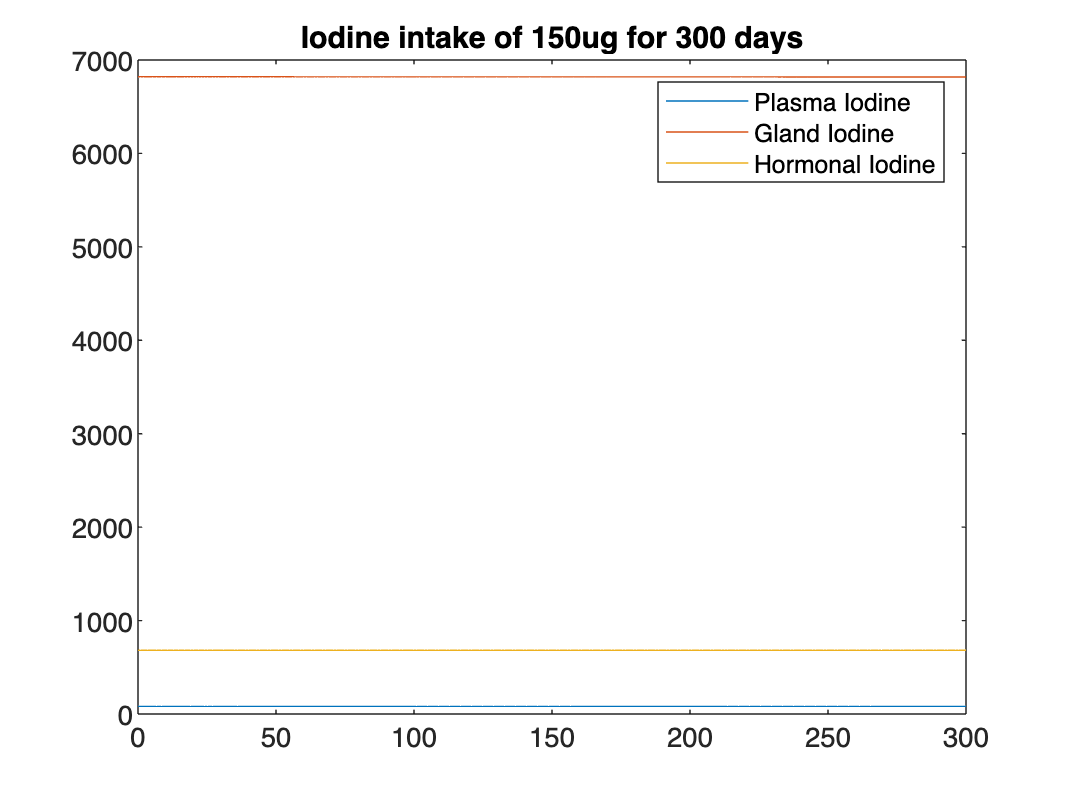

%Iodine intake of 150ug for 300 days
[t,y] = ode23('riggs150',[0 300],[81.2 6821 682]); 
plot(t,y)
title('Iodine intake of 150ug for 300 days'); 
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

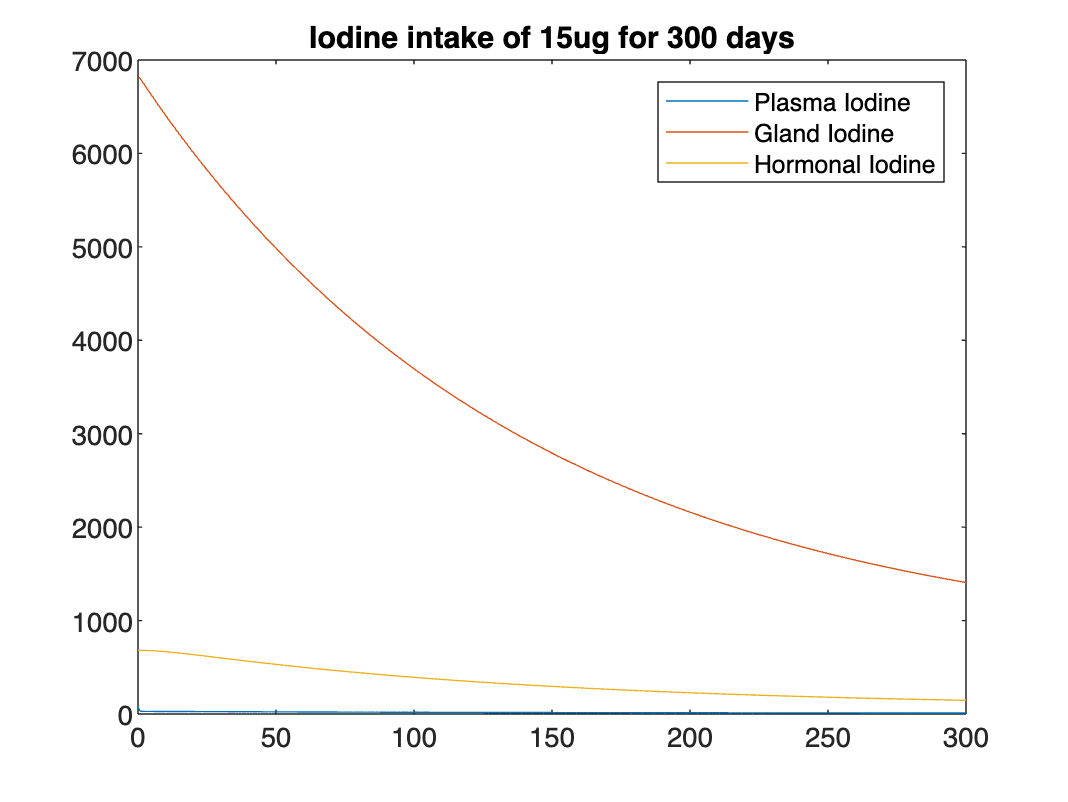

%Iodine intake of 15ug for 300 days
[t,y] = ode23('riggs15',[0 300],[81.2 6821 682]); 
plot(t,y)
title('Iodine intake of 15ug for 300 days'); 
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

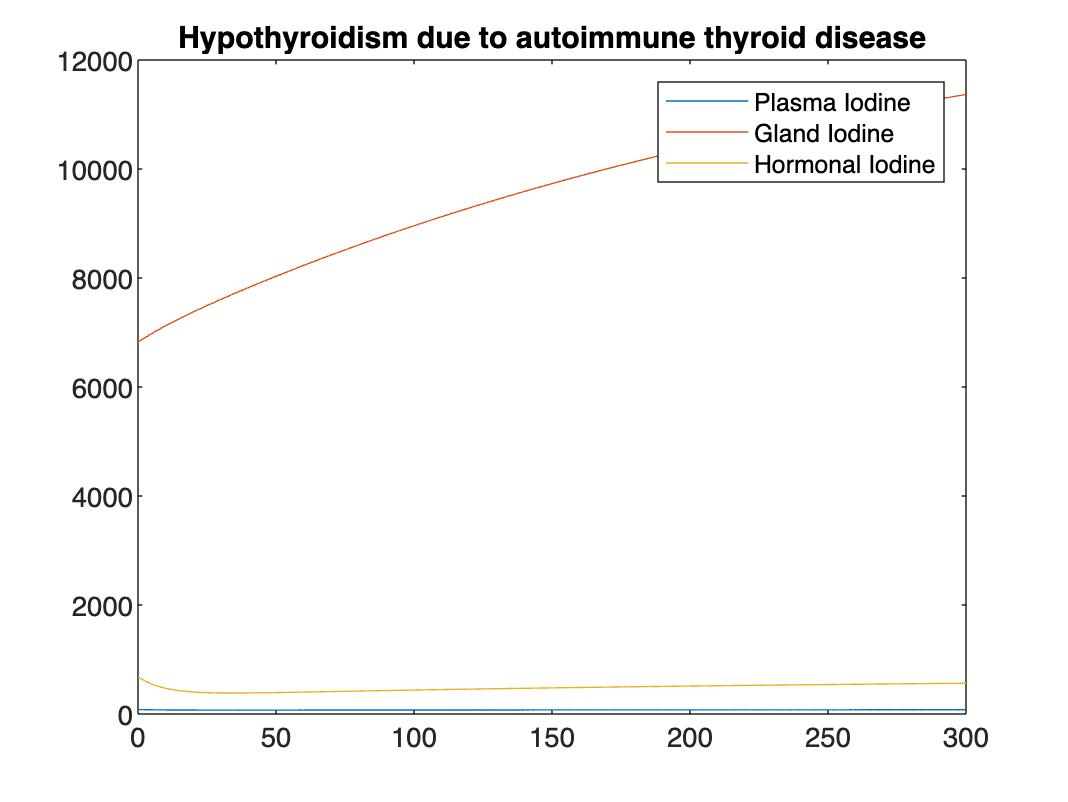

%Hypothyroidism due to autoimmune thyroid disease
%Hashimoto's disease
[t,y] = ode23('hashimoto',[0 300],[81.2 6821 682]); 
plot(t,y)
title('Hypothyroidism due to autoimmune thyroid disease'); 
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

%Hypothyroidism due to low Iodine intake
%Iodine intake of 150ug for 300 days
[t,y] = ode23('riggs150',[0 300],[81.2 6821 682]); 
plot(t,y)
title('Iodine intake of 150ug for 300 days'); 
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');


%Iodine intake of 15ug for 300 days
[t,y] = ode23('riggs15',[0 300],[81.2 6821 682]); 
plot(t,y)
title('Iodine intake of 15ug for 300 days'); 
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

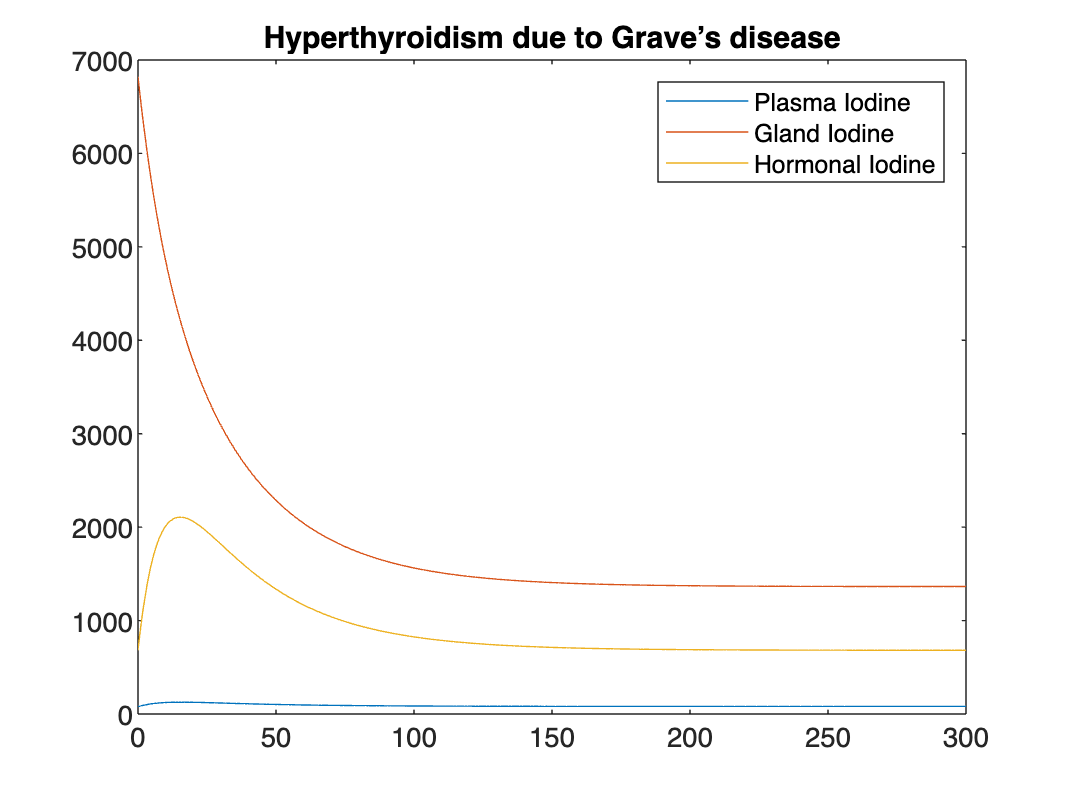

%Hyperthyroidism due to Grave’s disease
[t,y] = ode23('grave',[0 300],[81.2 6821 682]); 
plot(t,y)
title('Hyperthyroidism due to Grave’s disease'); 
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

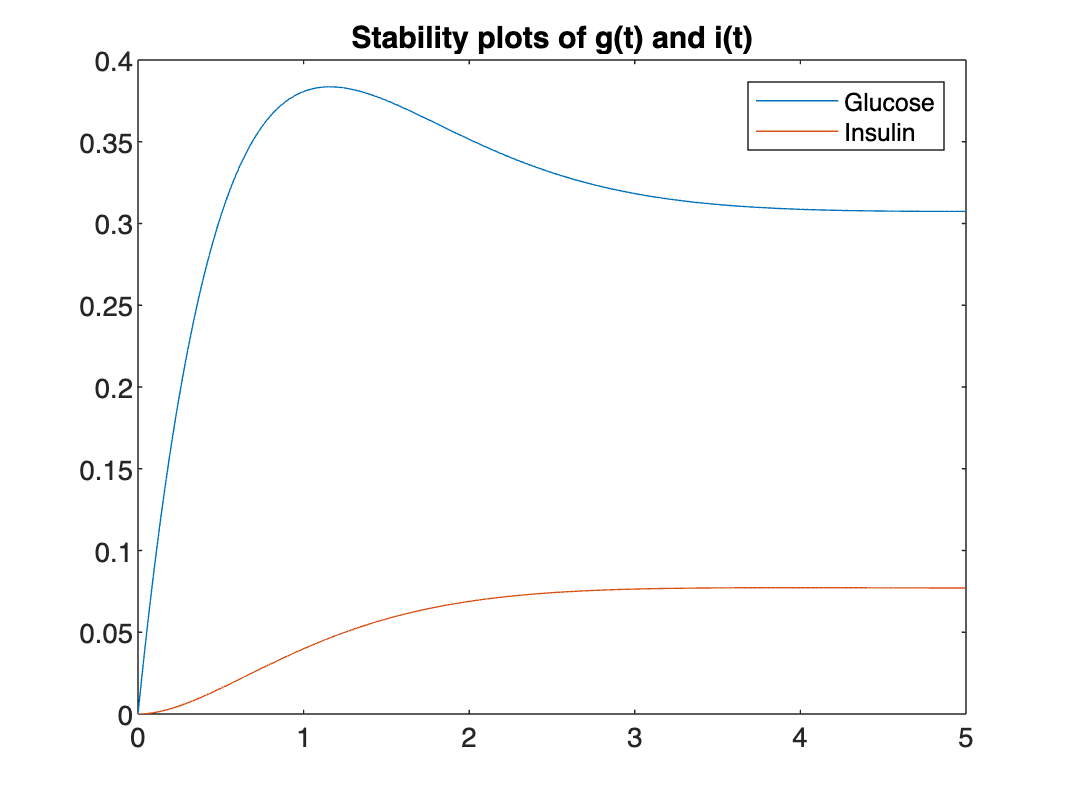

%Bolies’ Plasma-Glucose model
t = 0:0.01:5;
gt = (exp((-1.4).*t)).*(-(4/13)*cos((0.8).*t) + (37/52)*sin((0.8).*t)) + 4/13;
it = (exp((-1.4).*t)).*(-(1/13)*cos((0.8).*t) - (7/52)*sin((0.8).*t)) + 1/13;
plot(t, gt, t, it);
title('Stability plots of g(t) and i(t)');
legend('Glucose',"Insulin");

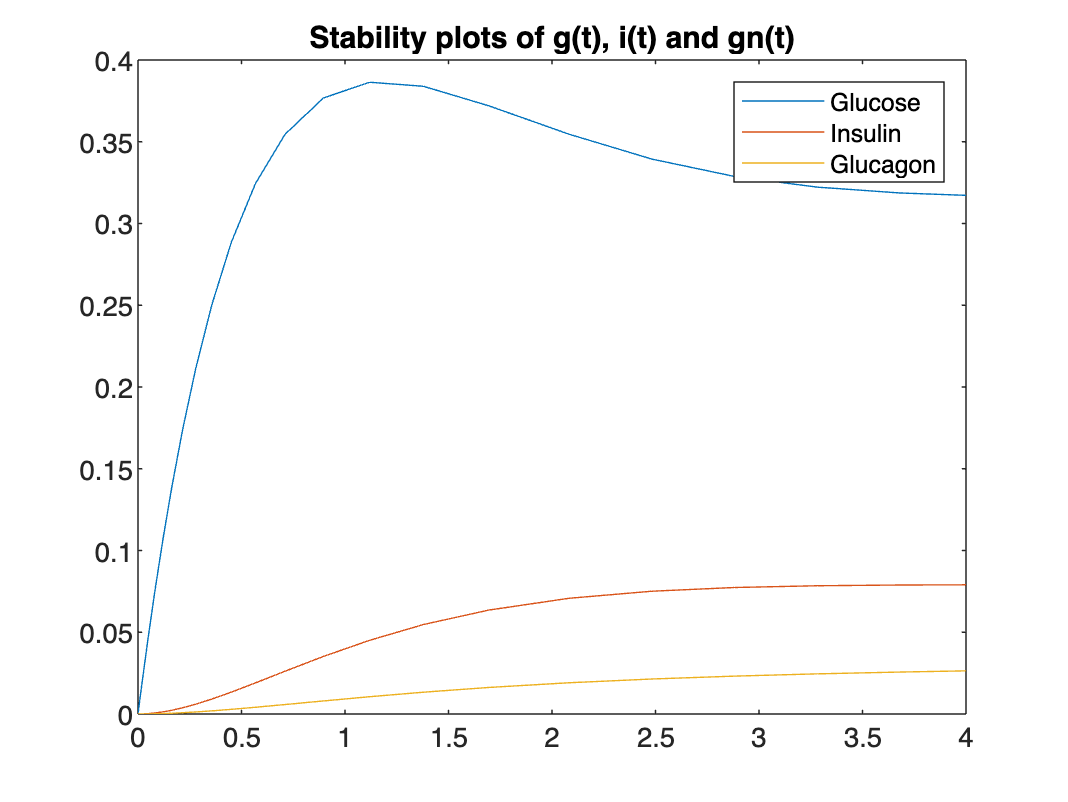

%Expanding Bolies’ Plasma-Glucose model including the effects of Glucagon
[t,y] = ode23('extendedBolies',[0 4],[0 0 0]); 
plot(t,y)
title('Stability plots of g(t), i(t) and gn(t)'); 
legend ('Glucose','Insulin','Glucagon');